# QEA 3 Solar House Project

Meagan Martin and Myles Lack-Zell

10/7/21

clear all
% System variables
ttVec=[1]; % tile thickness(es) [m] 
%ItVec=[.0325,0.034]; % insulation thickness(es) [m] (@ tspan(end)/120, perfectly centered w/ .0325 [m])
ItVec=[0.034]; % insulation thickness [m]
Aw=13; % window area [m^2]
AiIn=99.6; % inner surface area of insulation [m^2]
Ai=AiIn; % cross-sectional area of insulation for conduction [m^2] (neglecting corners and control)
hIn=15; % inside convective heat transfer coefficient [W/(m^2*K)]
hOut=30; % outside convective heat transfer coefficient [W/(m^2*K)]
hEq=0.7; % equivalent heat transfer coefficient through window [W/(m^2*K)]
k_i=0.04; % insulation (fiberglass) thermal conductivity [W/(m*K)]

% tile variables
tDensity=3000; % tile density [kg/m^3]
tSpecific=300; % tile specific heat [J/(kg*K)]

% initial conditions
T_aOut=-3+273.15; % outside air temperature (constant) [K] (-3 [°C])
T0=-3+273.15; % initial tile temperature [K] (-3 [°C])

% looping through to solve
i_n=1; % initialize It counter
for It=ItVec % cycle through insulation thicknesses
    t_n=1; % tt counter 
    for tt=ttVec % cycle through tile thicknesses
        % tile heat capacity calculations
        tVol=5.1*5*tt; % tile density [m^3]
        tMass=tVol*tDensity; % tile mass [kg]
        Ct=tMass*tSpecific; % tile heat capacity [J/K]
        
        %calculate thermal resistances and run ode45, then save in a matrix
        At=51+20.2*tt; % tile surface area [m^2]
        AiOut=108.6+5*It; % outer surface area of insulation [m^2]
        
        R_t_aIn = 1/(hIn*At); % Thermal Resistance (conv) b/w tile and internal air [K/W]
        R_aIn_i = 1/(hIn*Ai); % Thermal Resistance (conv) b/w internal air and walls [K/W]
        R_i = It/(k_i*Ai); % Thermal Resistance (cond) through insolation [K/W]
        R_i_aOut = 1./(hOut*AiOut); % Thermal Resistance (conv) from insolation to outside air [K/W]
        R_aIn_w = 1/(hIn*Aw); % Thermal Resistance (conv) of internal air to window [K/W]
        R_w = 1/(hEq*Aw); % Thermal Resistance of window [K/W]
        R_w_aOut = 1/(hOut*Aw); % Thermal Resistance (conv) fromm window to outside air [K/W]
        
        % solve differential equations (FUNCTION 'tempFun' AT END OF DOCUMENT)
        %tspan=[0,24*3600]; % time span [s] (24 [h])
        tspan=[0,20*86400]; % time span [s] (14 [days])
        %tspan=[0,30*86400]; % time span [s] (30 [days])
        options=odeset('MaxStep',3600); % set max step size for simulation [s] (60 [min]) (nice @ tspan(end)/120)
        [t,Tt]=ode45(@(t,Tt) tempFun(t,Tt,Aw,Ct,T_aOut,R_t_aIn,...
            R_aIn_i,R_i,R_i_aOut,R_aIn_w,R_w,R_w_aOut),tspan,T0,options); % solve equation for floor temp [K]
        
        % calculate internal air temperature
        R_outTotal=(R_t_aIn+(1/((1/(R_aIn_i+R_i+R_i_aOut))+(1/(R_aIn_w+R_w+R_w_aOut))))); % total thermal resistance leaving house [K/W]
        Ta=Tt-(R_t_aIn/R_outTotal).*(Tt-T_aOut); % calculate internal air temperature
        
        % unit conversions to make more readable plots
        Ta_celsius=Ta-273.15; % convert temperature to [°C]
        t_hours=t./3600; % convert time to [h]
        %t_days=t./86400; % convert time to [days]
        
        Temps(1:length(t),t_n:t_n+1,i_n)=[t_hours,Ta_celsius]; % add air temp data to Temps array
        %Temps(1:length(t),t_n:t_n+1,i_n)=[t_days,Ta_celsius]; % add air temp data to Temps array
        Temps(length(t)+1:end,t_n:t_n+1,i_n)=NaN(length(Temps)-length(t),2); % replace 0s in shorter vectors with NaN
        
        % test plot to make sure air temperature is correct
%         figure()
%         hold on
%         plot(t,Tt,'DisplayName','Tile')
%         plot(t,Ta,'DisplayName','Air')
%         hold off
%         legend('Location','best')
%         
        t_n=t_n+2; % add 2 tt counter 
    end
    i_n=i_n+1; % add 1 to It counter
end

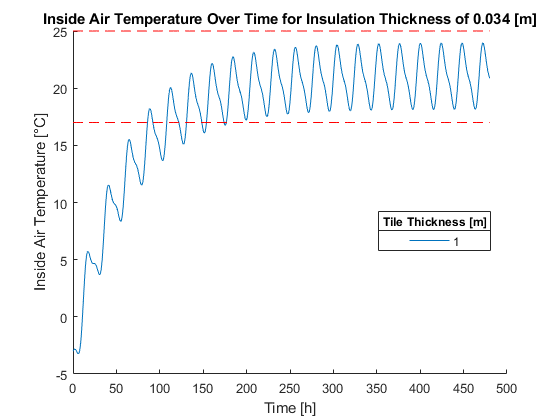

% Create a plot for each insulation thickness. Each plot has data for all
% tile thicknesses
for i=1:size(Temps,3)
    figure()
    hold on
    for n=1:2:size(Temps,2)
        plot(Temps(:,n,i),Temps(:,n+1,i),'-')
    end
    plot(Temps(:,1,i),ones(length(Temps(:,1,i)))*17,'--r') % plot min comfortable temp (17 [°C])
    plot(Temps(:,1,i),ones(length(Temps(:,1,i)))*25,'--r') % plot max comfortable temp (25 [°C])
    title('Inside Air Temperature Over Time for Insulation Thickness of ' + string(ItVec(i)) + ' [m]')
        % title pulls current insulation thickness
    xlabel('Time [h]'); ylabel('Inside Air Temperature [°C]')
    lgd=legend(string(ttVec),'Location','best');
    lgd.Title.String='Tile Thickness [m]';
end

#### 24 Plot of Full Data

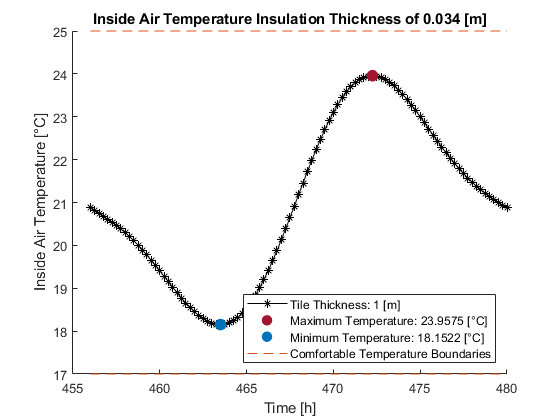

eqTemps=Temps(1825:end,:); % save final 24 hours of temperatures ([h] and [°C])
[minTemp,minInd]=min(eqTemps(:,2)); % find minimum temperature [°C]
[maxTemp,maxInd]=max(eqTemps(:,2)); % find minimum temperature [°C]

figure()
hold on
plot(eqTemps(:,1),eqTemps(:,2),'-*k') % plot temperature
plot(eqTemps(maxInd,1),maxTemp,'.','MarkerSize',30,'Color','#A2142F') % plot maximum temperature
plot(eqTemps(minInd,1),minTemp,'.','MarkerSize',30,'Color','#0072BD') % plot minimum temperature
plot(eqTemps(:,1),ones(length(eqTemps(:,1)))*17,'--','Color','#D95319') % plot min comfortable temp (17 [°C])
plot(eqTemps(:,1),ones(length(eqTemps(:,1)))*25,'--','Color','#D95319') % plot max comfortable temp (25 [°C])
title('Inside Air Temperature Insulation Thickness of ' + string(ItVec(1)) + ' [m]')
    % title pulls 1st insulation thickness
xlabel('Time [h]'); ylabel('Inside Air Temperature [°C]')
legend('Tile Thickness: '+string(ttVec)+' [m]','Maximum Temperature: '+string(maxTemp)+' [°C]',...
    'Minimum Temperature: '+string(minTemp)+' [°C]',...
    'Comfortable Temperature Boundaries','Location','southeast')

function dTdt = tempFun(t,Tt,Aw,Ct,T_aOut,R_t_aIn,R_aIn_i,R_i,R_i_aOut,R_aIn_w,R_w,R_w_aOut) % add input variables (tt=tile thickness, It=insulation thickness)
    % time-dependent variables
    qW=-361*cos((pi*t)/(12*3600))+224*cos((pi*t)/(6*3600))+210; % temp gradient perpendicular to window
    QdotIn=Aw*qW; % heat transfer rate into house through by solar radiation [W]
    
    QdotOut=(Tt-T_aOut)/(R_t_aIn+(1/((1/(R_aIn_i+R_i+R_i_aOut))+(1/(R_aIn_w+R_w+R_w_aOut)))));
        % heat transfer rate from tile to outside air [W]
    
    % ode
    dTdt=QdotIn/Ct-QdotOut/Ct; % tile temperature derivative
end